rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data
load diabetes.mat


length(labels_train==1)

ans = 300

length(labels_test==1)

ans = 168

sum(labels_train==1)/length(labels_train==1)

ans = 0.3167

sum(labels_test==1)/length(labels_test==1)

ans = 0.3690

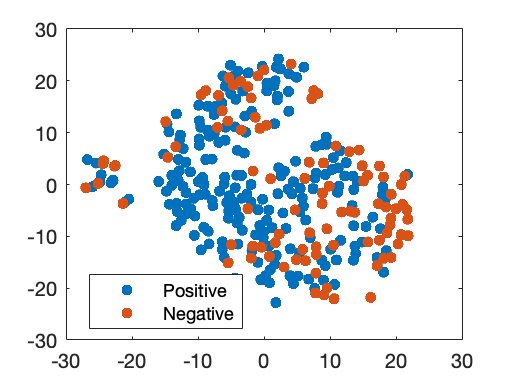

figure;
out = tsne(zscore(trainset),'Algorithm','exact','Distance','Euclidean');
gscatter(out(:,1),out(:,2),labels_train)
legend('Positive','Negative')

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_1411_4.png','Resolution',300)

run=[1:100];

simplex=[];
for r=run,
    [gam , sig2, cost] = tunelssvm({ trainset , labels_train , 'c', [], [], 'lin_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex=[simplex; gam, sig2, cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.022695
                                          F(X)=         0.25333
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 lin_kernel
 

 3. starting value:                   0.022695

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     2.533333e-01     -3.7856           initial 
     2           5     2.533333e-01     -3.7856           shrink 
     3           8     2.533333e-01     -3.7856           shrink 
     4          10     2.533333e-01     -3.7856           contract inside 
     5          12     2.533333e-01     -3.7856           contract outside 
optimisation terminated sucessfu

tend = toc;


fprintf('\n LINEAR: median gamma = %.2f  ', median(simplex(:,1)))


 LINEAR: median gamma = 0.03  

fprintf('\n LINEAR: median cost = %.2f  ', median(simplex(:,2)))


 LINEAR: median cost = 0.24  

run=[1:100];
simplex_rbf=[];
for r=run,
    [gam ,sig2 , cost] = tunelssvm({ trainset , labels_train , 'c', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex_rbf=[simplex_rbf; gam ,sig2 , cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         462.5687
                                          [sig2]        5024.8791
                                          F(X)=         0.24667
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   462.56871      5024.8791

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     2.466667e-01     6.1368        9.7222      initial 
     2           5     2.466667e-01     6.1368        9.7222      contract inside 
     3           9     2.466667e-01     6.1368        9.7222      shrink 
     4          11     2.466667e-01     6.1368        9.

tend = toc;

fprintf('\n RBF: median gamma = %.2f  ', median(simplex_rbf(:,1)))


 RBF: median gamma = 51.53  

fprintf('\n RBF: median sig = %.2f  ', median(simplex_rbf(:,2)))


 RBF: median sig = 416.33  

fprintf('\n RBF: median cost = %.2f  ', median(simplex_rbf(:,3)))


 RBF: median cost = 0.24  

run=[1:100];
simplex_poly=[];
for r=run,
    [gam, t, cost] = tunelssvm({ trainset , labels_train , 'c', [], [], 'poly_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex_poly=[simplex_poly; gam ,t(:,1), t(:,2) , cost];
end


   Determine initial hyperparameters for simplex...
  |-                                              -|
  **************************************************

 1. Simulated Annealing results:          [gam]         0.379
                                          [t]           1.5884
                                          [degree]      3
                                          F(X)=         0.38667
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 poly_kernel
 

 3. starting values:                   0.379      1.5884           3

 Iteration   Func-count    min f(x)    log(gamma)      log(t)        Procedure

     1           3     3.866667e-01     -0.9702         0.4627         initial   
     2           5     3.533333e-01     -3.3702         2.2627         expand   
     3           7     3.000000e-01     -4.5702         0.7627         expand   
     4      

tend = toc;

fprintf('\n Poly: median gamma = %.2f  ', median(simplex_poly(:,1)))


 Poly: median gamma = 0.00  

fprintf('\n Poly: median t = %.2f  ', median(simplex_poly(:,2)))


 Poly: median t = 24.53  

fprintf('\n Poly: median degree = %.2f  ', median(simplex_poly(:,3)))


 Poly: median degree = 3.00  

fprintf('\n Poly: median cost = %.2f  ', median(simplex_poly(:,4)))


 Poly: median cost = 0.28  

gam = 51.5;
sig2 = 416;

% Train the classification model.
[ alpha , b ] = trainlssvm ({ trainset , labels_train , 'c', gam , sig2 ,'RBF_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ trainset , labels_train , 'c', gam , sig2 ,'RBF_kernel'} , { alpha , b } , testset ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , labels_test ) 

ans = 0.8538

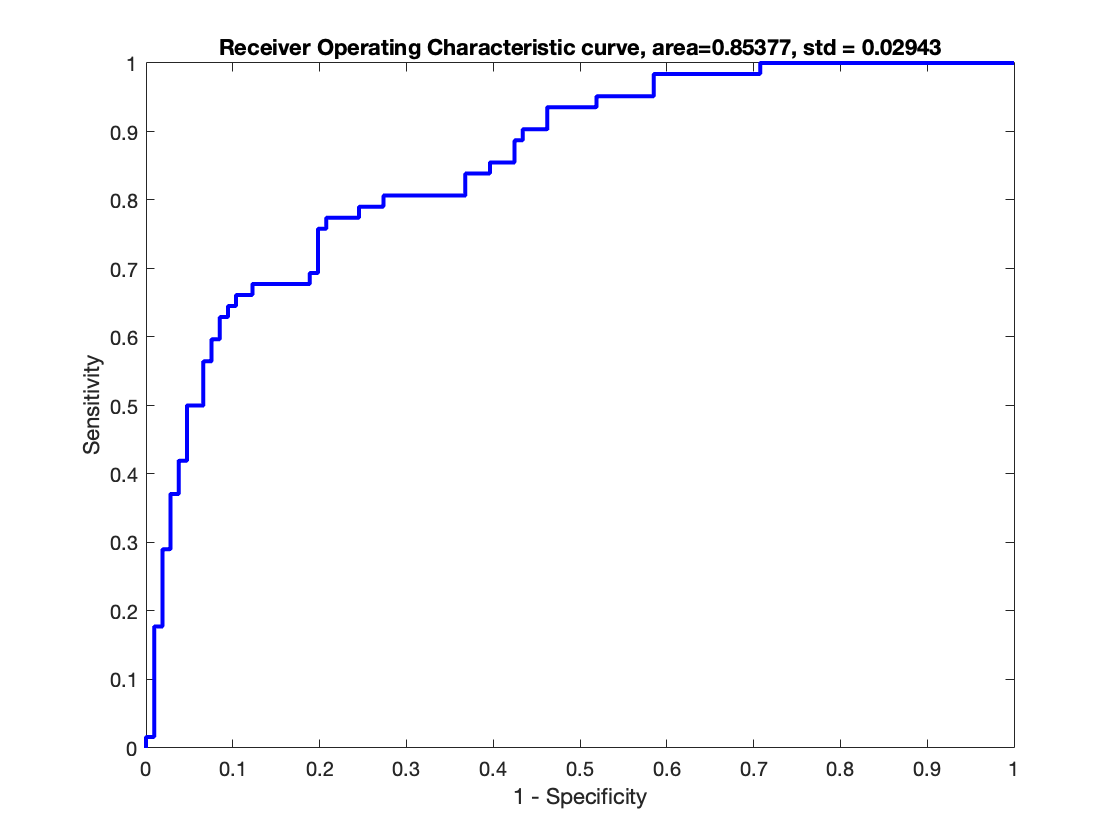


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/ .png','Resolution',300)

ans = 0.8440

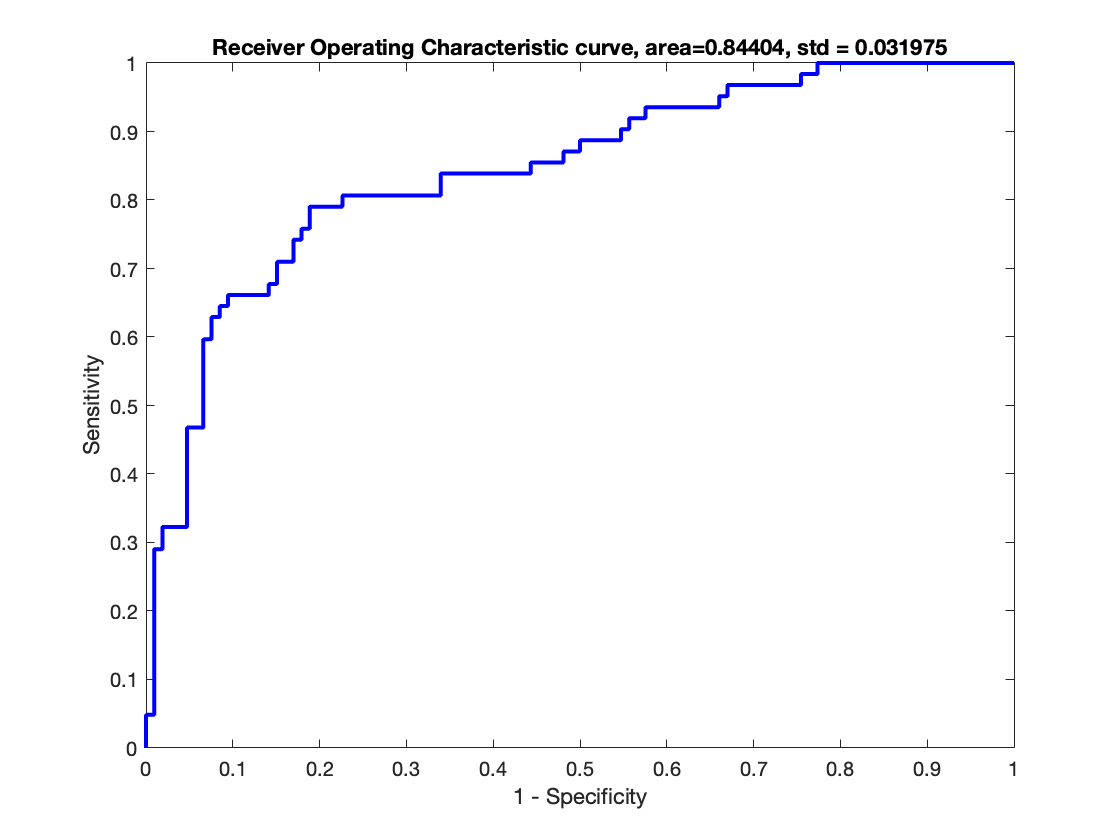

gam = 0.03;

% Train the classification model.
[ alpha , b ] = trainlssvm ({ trainset , labels_train , 'c', gam  ,[], 'lin_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ trainset , labels_train , 'c', gam  ,[],'lin_kernel'} , { alpha , b } , testset ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , labels_test) 